# Triangulate scene points

Extracts $n$ scene point given at least 2 calibrated cameras and $n$ projections in their images (namely, $n$ pixels). This means that in order to get a 3D scene point $M$ we can just have (at least) two images and indicate on those images the $m$ point which corresponds to the $M$ point wanted. Of course, this process can be reproduced to triangulate $n$ scene points, as was implemented in this function: given a $P$ matrix of dimensions $3 \times 4 \times p$ (which aggregates $p$ PPM matrices) and a $m$ matrix of dimensions $3 \times n \times p$ (which aggregates $n$ points for each $P_i$ matrix), we obtain a $M$ matrix of dimensions $4 \times n$, which are the points triangulated from the $n$ image points given for each $P_i$ matrix.

The theory behind this is very easy: in the ideal case of a two-camera system, namely $C_1$ and $C_2$, we take a picture from each, producing two images, namely $I_1$ and $I_2$; those images have as principal points respectevely $u_0$ and ${u'}_0$ and potrait with respectevely $u$ and $u'$ a scene point $M = [x_0, 0, z_0, 1]$, as we assume that everything (so $C_1$, $C_2$ and $M$) is on the same vertical plane, namely $y = 0$ (from this we also have $v = 0$ and $v' = 0$ in the images). 

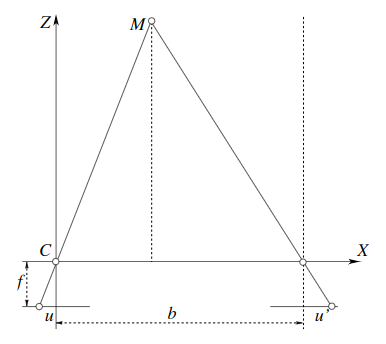

Using the proportionality of the triangles (and recalling that $u = 0$ and $u' = 0$ w.r.t. $I_1$ and $I_2$ and that $C = 0$ because is the origin of the reference system) we get


$$I_1 \to \frac{f}{z_0} = \frac{u_0 - u}{x_0 - C} = \frac{-u}{x_0} \qquad\qquad I_2 \to \frac{f}{z_0} = \frac{u' - {u'}_0}{C' - x_0} = \frac{u'}{b - x_0}$$


which algebraically ensures


$$x_0 = b \frac{-u}{u' - u} \qquad z_0 = b \frac{f}{u' - u}$$


With this we can see that just by knowing the two pixels $u$ and $u'$, the focal distance $f$ (or alternatively $\alpha_u$ and $\alpha_v$ in a pixellized camera) and the **baseline** $b$ (namely, the parallel translation distance between the two cameras) we can triangulate the point $M$ and obtain its exact position in the scene (without the usual scaling factor). When $b$ is unknown, the $M$ point position can still be calculated, but it will be subjected to an uncalculatable scale factor (becuase the problem is now underconstrained).

In a general scenario now, given a scene potraied by two images $I_1$ and $I_2$ taken from two cameras $P$ and $P'$, in which we can distinguish clearly the projections $m$ and $m'$ of the same unknown scene point $M$, we can calculate that scene point using


$$m \simeq PM = \left[\matrix{p_1^T \cr p_2^T \cr p_3^T}\right] M = \left[\matrix{p_1^T M \cr p_2^T M \cr p_3^T M}\right] \simeq \left[\matrix{\frac{p_1^T M}{p_3^T M} \cr \frac{p_2^T M}{p_3^T M} \cr 1}\right] = \left[\matrix{u \cr v \cr 1}\right]$$



$$\Longrightarrow\quad \begin{cases}u = \frac{p_1^T M}{p_3^T M} & \\ v = \frac{p_2^T M}{p_3^T M} & \end{cases} \quad\Longrightarrow\quad \begin{cases}u p_3^T M = p_1^T M & \\ v p_3^T M = p_2^T M & \end{cases} \quad\Longrightarrow\quad \begin{cases} (p_1^T - u p_3^T) M = 0 & \\ (p_2^T - v p_3^T) M = 0 & \end{cases} \quad\Longrightarrow\quad \left[\matrix{(p_1^T - u p_3^T) \cr (p_2^T - v p_3^T)}\right] M = 0$$


As we can see the $2 \times 4$ matrix on the left is not enough to calculate completely $M$, and that's why we need a second point (and thus a second camera) for the triangulation process (we follow the same steps as above), so we can have a $4 \times 4$ matrix


$$\left[\matrix{(p_1^T - u p_3^T) \cr (p_2^T - v p_3^T) \cr ({p'}_1^T - u' {p'}_3^T) \cr ({p'}_2^T - v' {p'}_3^T)}\right] M = 0$$


and calculate completely $M$ using SVD (we can still use more than 2 cameras and obtain an even better result, less subjected to human error given by the selected pixels).

Unfortunately, we don't know if the cameras provided are aligned and pointing in the same direction, so their provided $m$ points might not belong to the ideal images shown above and thus the baseline $b$ (which can be calculated as the distance between the center points) can't give us the actual position of the $M$ points. For this task, we will need to *rectify* the images, but this topic will be reviewed later on.

function [ M ] = triangulate(P, m)

if size(P,1) ~= 3 && size(P,2) ~= 4
    error('P matrix dimensions must be 3-by-4-by-n');
end

n_cameras = size(m,3);
if n_cameras < 2
    error("Must have at least 2 cameras (%s was given)", n_cameras);
end

if size(m,1) ~= 3
    error("Image points must be given as homogeneous coordinates");
end
if size(m,3) ~= n_cameras
    error("Each camera must have an image point");
end

n_points = size(m,2);

P = P./P(3,4,:);
m = m./m(3,:,:);

% we build the left tensor of dimensions 2p-by-4-by-n (namely an above 
% mentioned matrix, 2p-by-4, for every M point wanted)
A = zeros(2*n_cameras,4,n_points);
for i=1:n_cameras
    % this one is a little bit tricky: we calculate each couple of rows
    % (a couple for every camera, as viewed above) iteratively, and each 
    % row is calculated using outer multiplication (namely m'.*P); by 
    % doing so, we compute every row calculation of a singular camera for 
    % each point simultaneously
    A(2*i-1,:,:) = ( P(1,:,i) - m(1,:,i)'.*P(3,:,i) )';
    A(2*i,  :,:) = ( P(2,:,i) - m(2,:,i)'.*P(3,:,i) )';
end

M = zeros(4,n_points);
for i=1:n_points
    [~,~,V] = svd(A(:,:,i),'econ');
    M(:,i) = V(:,end);  % a null verctor is for sure the last column (lemma from SVD th.)
end
M = M./M(4,:);

end
